# PMSM Frequency Response Estimation

This script performs a frequency response estimation of the inner current control loop and the outer velocity control loop of the [FOC controller](matlab:load_system('pmsm_foc_drive'); open_system('pmsm_foc_drive/PMSM Controller/PMSM Field-Oriented Controller','force');). You can then assess the stability margin and speed of the two closed loops from the resulting Bode plot of the inner and outer open-loop transfer functions. You can iteratively adjust the gains of the controllers in the *SystemParams.m* script to achieve the desired stability margins.

In this example you will assess the performance of a set of controller gains. These gains are already tuned for the inner and outer loop PID controllers, for the default drive parameters, and the 

## 1. Setup the Model

Load the model:

model = 'pmsm_foc_drive';
load_system(model);
% Load system parameters
SystemParams;

SystemParams.m successful run


Select the choice of iDref and iQref tables. Choose between original or optimized.

idqrefchoice = "Optimized"; % Choice of iDrefMat and iQrefMat for controller outer loop
if strcmp(idqrefchoice, "Optimized")
    if ~exist('OptimalControllerParams', 'var')
        % Run optimization to load OptimalControllerParams;
        ControllerOptimization;
    end
    ControllerParams = OptimalControllerParams;
end
set_param([bdroot, '/PMSM Controller'], 'ControllerParameters', 'ControllerParams');

Select the fidelity level for the `Inverter` subsystem. The lowest fidelity is `Averaged`, and the highest is `Switching(Tabulated).` The simulation time increases for models with higher fidelity.

inverterfidelity = "Averaged";
set_param([model '/Inverter'],'LabelModeActiveChoice', inverterfidelity)

Select the operating point for this analysis:

TestScenarioParams.RotorSpeedRef_rpm = 3000; % rpm
TestScenarioParams.StepTorqueAfter_Nm = 80; % N*m

## 2. Inner Control Loop for Current

The frequency response estimation is first carried out for the[ inner control loop](matlab:load_system('pmsm_foc_drive'); open_system('pmsm_foc_drive/PMSM Controller/PMSM Field-Oriented Controller/Inner loop control/PMSM Current Controller with Pre-Control','force')), that controls the d-axis and q-axis currents. A constant value for $$i_{q,ref} $ and $$i_{d,ref}$$is used. The motor spins at a constant reference speed through a [constant velocity source](matlab:load_system('pmsm_foc_drive'); open_system('pmsm_foc_drive/Constant velocity source/ON')) on the mechanical shaft.

### 2.1 Estimation Parameters

To define the estimation experiment in the [Frequency Response Estimator block](matlab:load_system('pmsm_foc_drive'); open_system('pmsm_foc_drive/PMSM Controller/PMSM Field-Oriented Controller/Inner loop control/PMSM Current Controller with Pre-Control/Estimator/ON/Estimator')), create a structure with the main parameters. The Estimator block sums a sinusoidal excitation signal based on the frequencies of interest to its input signal (i.e. the error signal in the control loop). The block estimates the open-loop transfer function by observing how the sinusoidal perturbations are fed back around the control loop. The following considerations were made for the estimation:

- The experiment comprises three simulations, one for every frequency decade.

- To reduce the total simulation time, this script specifies fewer values for the lower frequencies.

- The excitation signal injected in the loop has different amplitude values. The excitation signal has a visible effect on the error signal and the measured output (which are the inputs to the Estimator block), without destabilizing the system. You can examine these signals in the [Simulation Data Inspector](matlab:Simulink.sdi.view) after an estimation run completes by expanding the *frestdata* signal bus.

InnerLoopParams = struct;
InnerLoopParams.model = model;
InnerLoopParams.loop = "inner";
InnerLoopParams.numOfEstPeriod = [2; 6]; % Number of estimation periods
InnerLoopParams.numOfSetPeriod = [1; 3]; % Number of settling periods
InnerLoopParams.decades = [1 2; 2 4]; % Frequency decades: [1,2] corresponds to the decade [10^1,10^2] rad/s
InnerLoopParams.amplitude = [20; 10]; % Amplitude of the excitation signal
InnerLoopParams.nfreq = [5; 10]; % Number of frequencies to estimate in each decade
InnerLoopParams.frequencies = "logspace(" + InnerLoopParams.decades(:,1) + ...
    "," + InnerLoopParams.decades(:,2) + "," + InnerLoopParams.nfreq + ")";
InnerLoopParams.foc_controller = model + "/PMSM Controller"; % Path to the FOC controller
InnerLoopParams.pid_controller = InnerLoopParams.foc_controller + "/PMSM Field-Oriented Controller/Inner loop control" + ...
    "/PMSM Current Controller with Pre-Control"; % Path to the PID controller
InnerLoopParams.velocity_source = model + "/Constant Velocity Source"; % Path to constant velocity source

You can compute the experiment duration based on the estimation parameters. To guarantee that the estimation has enough time to complete, set the simulation time accordingly.

InnerLoopParams.expLength = computeSimTime(InnerLoopParams, ControllerParams.SampleTime);
estStart = 0.2;
estStop = estStart + InnerLoopParams.expLength + 0.1;
simStop = estStop + 0.1;

Finally, choose the operating point for the inner loop:

ControllerParams.idRef = -20; % A
ControllerParams.iqRef = 180; % A

To define the model parameters and the block parameters to run the simulations, use the simulation input objects:

in = createSimInput(InnerLoopParams,TestScenarioParams,ControllerParams,estStart,estStop,simStop); 

### **2.2 Run Simulations and Plot Frequency Response**

Select whether to run the estimation simulation or use the saved estimation results. 

projObj = currentProject;
projRootFolder = projObj.RootFolder;
clear projObj;
simInnerLoop = true;
if simInnerLoop
    useParallel = false; % Only possible if Parallel Computing Toolbox is installed
    tic;
    [sys_estim, sys_estim_online] = runSimulation(in, InnerLoopParams, useParallel);
    toc;
    % Save results with unique filename
    filename = "inner_estim_" + string(datetime('now','Format','dMMy_HH_mm_ss')) + ".mat";
    save(fullfile(projRootFolder, "data", "output",filename), "InnerLoopParams", "sys_estim_online", "sys_estim");
    % If default results "inner_estim.mat" do not exist, save this results
    % as default data "inner_estim.mat" too
    if ~exist(fullfile(projRootFolder, "data", "output","inner_estim.mat"), "file")
        save(fullfile(projRootFolder, "data", "output","inner_estim.mat"), "InnerLoopParams", "sys_estim_online", "sys_estim")
    end
else
    % Load default results
    filename = fullfile(projRootFolder, "data", "output", "inner_estim.mat"); %#ok<UNRCH> 
    data = load(filename);
    sys_estim = data.sys_estim;
    sys_estim_online = data.sys_estim_online;
end

[16-Nov-2021 14:31:55] Running simulations...
[16-Nov-2021 14:41:21] Completed 1 of 2 simulation runs
[16-Nov-2021 14:44:36] Completed 2 of 2 simulation runs


Elapsed time is 767.147256 seconds.


% Re-load results
data = load(filename);
sys_estim = data.sys_estim;

Plot the Bode diagram of the estimated open-loop transfer function (or "return ratio").

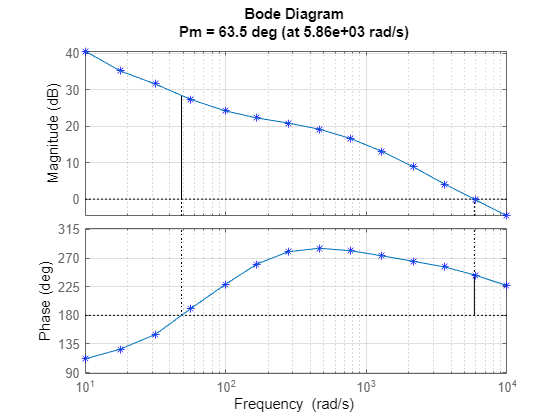

f1 = figure;
b1 = bodeplot(sys_estim, "b*");
hold on 
margin(sys_estim);
grid on
opt = getoptions(b1);
opt.Title.String = "Bode Diagram" + newline + "Pm" + extractAfter(opt.Title.String, "Pm");
setoptions(b1, opt);
hold off;

From the Bode diagram, observe that the inner loop FOC controller achieves a good stability margin in closed-loop, with a phase margin above 60 degrees, and a bandwidth above 5500 rad/s.

## 3. Outer Control Loop for Velocity

Perform the same analysis on the[ outer control loop](matlab:load_system('pmsm_foc_drive'); open_system('pmsm_foc_drive/PMSM Controller/PMSM Field-Oriented Controller/Outer loop control/Velocity Controller','force')), which controls the motor speed and produces the current references $$i_{dq,ref}$$ for the inner control loop. To reduce the total simulation time, this example defines a lower amount of experiments in the low-frequency decades.

### 3.1 Estimation Parameters

OuterLoopParams = struct;
OuterLoopParams.model = model;
OuterLoopParams.loop = "outer";
OuterLoopParams.numOfEstPeriod = [2; 3; 15]; % Number of estimation periods
OuterLoopParams.numOfSetPeriod = [1; 1; 5]; % Number of settling periods
OuterLoopParams.decades = [0 2; 2 3; 3 4]; % Frequency decades: [1,2] corresponds to the decade [10^1,10^2] rad/s
OuterLoopParams.amplitude = [1; 1; 1]; % Amplitude of the excitation signal
OuterLoopParams.nfreq = [5; 5; 5]; % Number of frequencies to estimate in each decade
OuterLoopParams.frequencies = "logspace(" + OuterLoopParams.decades(:,1) + ...
    "," + OuterLoopParams.decades(:,2) + "," + OuterLoopParams.nfreq + ")";
OuterLoopParams.foc_controller = model + "/PMSM Controller/PMSM Field-Oriented Controller"; % Path to the FOC controller
OuterLoopParams.pid_controller = OuterLoopParams.foc_controller + "/Outer loop control/Velocity Controller"; % Path to the PID controller
OuterLoopParams.expLength = computeSimTime(OuterLoopParams, ControllerParams.SampleTime);
OuterLoopParams.velocity_source = model + "/Constant Velocity Source"; % Path to constant velocity source
estStart = 0.2;
estStop = estStart + OuterLoopParams.expLength + 0.1;
simStop = estStop + 0.1;

To define the model parameters and the block parameters to run the simulations, use the simulation input objects:

in = createSimInput(OuterLoopParams,TestScenarioParams,ControllerParams,estStart,estStop,simStop);

### **3.2 Run Simulations and Plot Frequency Response**

Select whether to run the estimation simulation or use saved estimation results. 

simOuterLoop = true;
if simOuterLoop
    useParallel = false; % Only possible if Parallel Computing Toolbox is installed
    tic;
    [sys_estim, sys_estim_online] = runSimulation(in, OuterLoopParams, useParallel);    
    toc;
    % Save results with unique filename
    filename = "outer_estim_" + string(datetime('now','Format','dMMy_HH_mm_ss')) + ".mat";
    save(fullfile(projRootFolder, "data",filename), "OuterLoopParams", "sys_estim_online", "sys_estim");
    % If default results "outer_estim.mat" do not exist, save this results
    % as default data "outer_estim.mat" too
    if ~exist(fullfile(projRootFolder, "data", "output","outer_estim.mat"), "file")
        save(fullfile(projRootFolder, "data", "output","outer_estim.mat"), "OuterLoopParams", "sys_estim_online", "sys_estim");
    end
else
    % Load default results
    filename = fullfile(projRootFolder, "data", "output", "outer_estim.mat"); %#ok<UNRCH> 
    data = load(filename);
    sys_estim = data.sys_estim;
    sys_estim_online = data.sys_estim_online;
end

[16-Nov-2021 14:44:45] Running simulations...
[16-Nov-2021 15:38:04] Completed 1 of 3 simulation runs
[16-Nov-2021 15:39:52] Completed 2 of 3 simulation runs
[16-Nov-2021 15:41:11] Completed 3 of 3 simulation runs


Elapsed time is 3398.747234 seconds.


%Re-load results
data = load(filename);
sys_estim = data.sys_estim;
sys_estim_online = data.sys_estim_online;

Plot the Bode diagram of the estimated open-loop transfer function (or "return ratio").

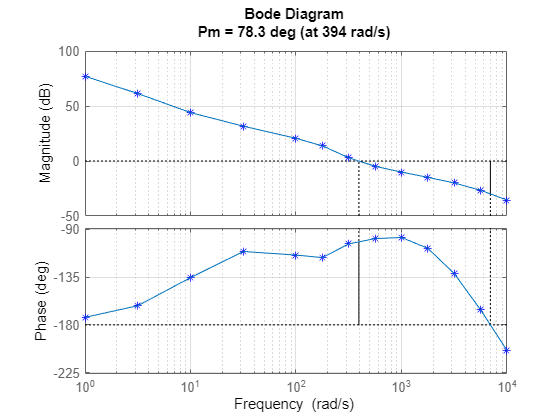

f2 = figure;
b2 = bodeplot(sys_estim, "b*");
hold on 
margin(sys_estim);
grid on
opt = getoptions(b2);
opt.Title.String = "Bode Diagram" + newline + "Pm" + extractAfter(opt.Title.String, "Pm");
setoptions(b2, opt);
hold off;

From the Bode diagram, observe that the outer-loop FOC controller also achieves a good stability margin in closed-loop, with enough phase margin, and a bandwidth that is an order of magnitude slower than the bandwidth of the faster inner loop.

## Helper Functions

function in = createSimInput(P,TestScenarioParams,ControllerParams,estStart,estStop,simStop)
    % Create simulation input objects based on the estimation parameters
    % specified in P.
    nSims = numel(P.frequencies);
    in = Simulink.SimulationInput.empty(0,nSims);
    estimator = P.pid_controller + "/Estimator";
    estimatorBlk = estimator + "/ON/Estimator";
    startBlk = estimator + "/ON/start";
    stopBlk = estimator + "/ON/stop";
    
    for iSim = 1:nSims
        % Define the model
        in(iSim) = Simulink.SimulationInput(P.model);
        % Pass TestScenarioParams and ControllerParams as a Variable to the simulation input
        in(iSim) = in(iSim).setVariable("TestScenarioParams", TestScenarioParams);
        in(iSim) = in(iSim).setVariable("ControllerParams", ControllerParams);
        % Enable correct variants for estimation
        in(iSim) = in(iSim).setBlockParameter(P.foc_controller, "LabelModeActiveChoice", "Estimation");
        in(iSim) = in(iSim).setBlockParameter(estimator, "LabelModeActiveChoice", "ON");
        % Set the right variant choices
        if strcmp(P.loop,"inner")
            in(iSim) = in(iSim).setBlockParameter(P.pid_controller + "/Reference Source", "LabelModeActiveChoice", "ON");
            in(iSim) = in(iSim).setBlockParameter(P.velocity_source, "LabelModeActiveChoice", "ON");
        elseif strcmp(P.loop,"outer")
            in(iSim) = in(iSim).setBlockParameter(P.velocity_source, "LabelModeActiveChoice", "OFF");
        end
        % Define parameter values
        in(iSim) = in(iSim).setBlockParameter(estimatorBlk, "Frequencies", P.frequencies(iSim));
        in(iSim) = in(iSim).setBlockParameter(estimatorBlk, "Amplitudes", num2str(P.amplitude(iSim)));
        in(iSim) = in(iSim).setBlockParameter(estimatorBlk, "NumOfEstPeriod", num2str(P.numOfEstPeriod(iSim)));
        in(iSim) = in(iSim).setBlockParameter(estimatorBlk, "NumOfSetPeriod", num2str(P.numOfSetPeriod(iSim)));
        in(iSim) = in(iSim).setBlockParameter(startBlk, "Time", num2str(estStart));
        in(iSim) = in(iSim).setBlockParameter(stopBlk, "Time", num2str(estStop(iSim)));
        % Define model settings
        in(iSim) = in(iSim).setModelParameter("StopTime", num2str(simStop(iSim)));
    end % for
end % createSimInput


function expLengths = computeSimTime(P, Ts) 
    % Compute total estimation time based on the estimation parameters
    % specified in P and the control sample time Ts
    
    nSims = numel(P.frequencies);
    expLengths = zeros(nSims,1);
    for j = 1:nSims
        expLengths(j) = sum( reshape(2*pi./eval(P.frequencies(j)),P.nfreq(j),1) ...
            .*(P.numOfEstPeriod(j).*ones(P.nfreq(j),1) + P.numOfSetPeriod(j).*ones(P.nfreq(j),1)) ) + ...
            2*Ts*P.nfreq(j);
    end % for
end % computeSimTime


function [sys_estim, sys_estim_online] = runSimulation(in, P, useParallel)
    if useParallel 
        simOut = parsim(in,"ShowSimulationManager","on","ShowProgress","on");
    else
        simOut = sim(in,"ShowSimulationManager","on","ShowProgress","on");
    end
    % Extract frequency response from simulation output data:
    nSims = numel(in);
    frdata = cell(0,nSims);
    frestdata = cell(0,nSims);
    for iSim = 1:nSims
        frdata{iSim} = frd( simOut(iSim).logsout.getElement("frdata").Values.Data(end,:), ...
            eval(P.frequencies(iSim)) );
        frestdata{iSim} = simOut(iSim).logsout.getElement("frestdata").Values;
    end % for
    
    % Combine the frequency responses of the different decades:
    sys_estim_online = frdata{1};
    sys_estim = frestimate(frestdata{1}, eval(P.frequencies(1)), 'rad/s');
    for iSim = 2:nSims
        newdecade1 = frdata{iSim};
        newdecade2 = frestimate(frestdata{iSim}, eval(P.frequencies(iSim)), 'rad/s');
        sys_estim_online = combinefreqresp(sys_estim_online, newdecade1);
        sys_estim = combinefreqresp(sys_estim, newdecade2);
    end % for
end % runSimulation

Copyright 2022 The MathWorks, Inc